Jordan Carlson V00714886 - ECE 485 Final Exam

Question 1



clear all        % clear Matlab's memory for debugging

load Data_Ques_1.mat         %load the matlab data file

who                               %display the loaded variables


Your variables are:

Classes  Data     




disp('The unique Classes are:')

The unique Classes are:


unique(Classes)                           %display the unique class entries

ans =      1     2



Mdl = fitcdiscr(Data,Classes)            % Matlab's built-in fitcdiscr function is used to return the fitted discriminant 

Mdl =   ClassificationDiscriminant
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2]
           ScoreTransform: 'none'
          NumObservations: 1000
              DiscrimType: 'linear'
                       Mu: [2×25 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


                                           % analysis models based on the predictors

class1Points = (Mdl.Mu(1,:))'

class1Points =     2.4072
   -9.6411
    0.7464
    6.4121
   13.9618
   20.8815
   21.1906
    8.9789
   -0.5148
  -10.8062


class2Points = (Mdl.Mu(2,:))'

class2Points =     2.1279
  -10.8152
   -0.4243
    7.7375
   15.4678
   22.4694
   20.9527
   10.1858
   -0.5050
  -11.2207


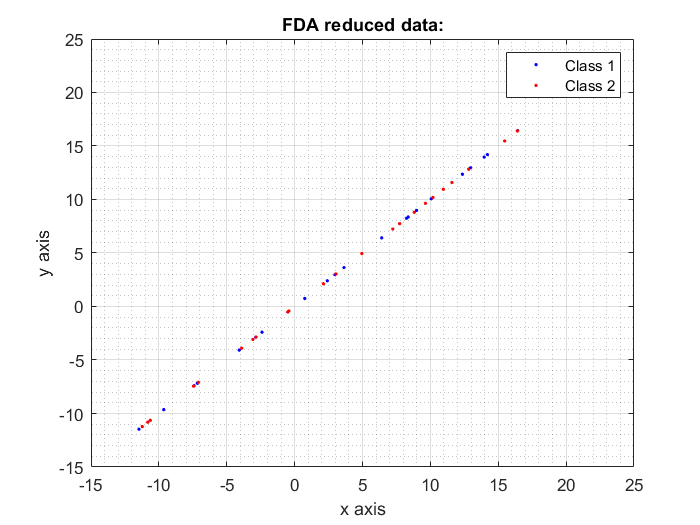




plot(class1Points,class1Points,'b.') % plot Class 1 data with red dots
hold on % put hold on on the plot to allow more than one plot to be done on the same plot
plot(class2Points,class2Points,'r.') % plot Class 2 data with blue dots

xlabel('x axis')  % label the x-axis, y-axis, and title of the plot
ylabel('y axis')
title('FDA reduced data:')
legend('Class 1', 'Class 2') % put a legend on the plot
grid on 

grid minor %turn on minor grid markings 

hold off

Now to find if they are gaussian

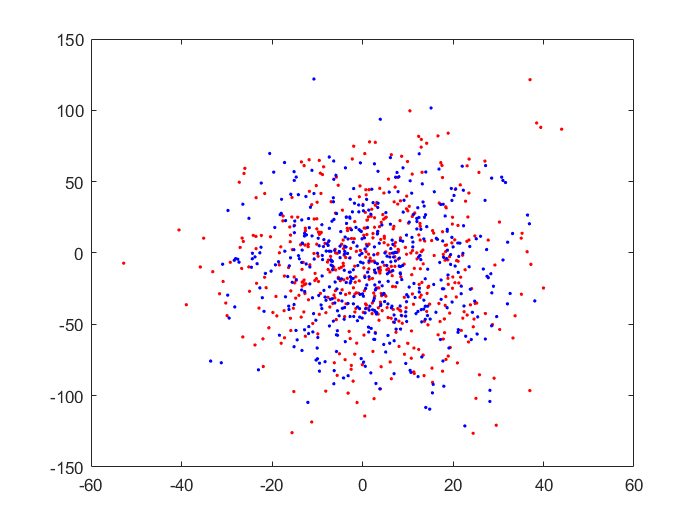


class1Index = find(Classes == 1); % saves class 1 point indices
class2Index = find(Classes == 2); % saves class 2 point indices

plot(Data(class1Index,1),Data(class1Index,2),'r.') % plot Class 1 data with red dots
hold on % put hold on on the plot to allow more than one plot to be done on the same plot
plot(Data(class2Index,1),Data(class2Index,2),'b.') % plot Class 2 data with blue dots


% using Matlab's fitdist function, these are indeed Gaussian, so to find
% the full function the means and covariances are needed

class1 = Data(class1Index,:)

class1 =    -4.2048    3.0565   -1.5119    1.9204    6.8136   18.0973   28.6349   -3.5698   -1.3491  -17.6945   12.4532   33.7786   15.8386    4.1709  -13.0420   -3.4055   24.6861   -3.5663   13.0012   16.5044  -13.7807  -12.7005  -11.1778   31.5039  -14.1205
   37.1985   -7.9555  -22.2809    0.6755   20.3032    4.4676   21.5310    0.0044    2.7128  -12.1781  100.9952    9.3282    7.0287    8.9289   -2.0276   -1.4741   36.3065   -3.1737   15.2358   -0.1934    2.7027   15.7538  -19.6161   40.4137   24.4146
   21.2867  -20.9837  -19.0044   14.4531   20.2969   32.0765    6.6721   10.4608   -4.3120    1.7468  -48.4373  -10.0421   10.3745   37.1630  -39.7380   13.1949   -7.7215   -1.1980   13.8250   12.8815  -23.6071   10.2994   35.7743   34.4734  -10.3455
    3.9589  -95.2673    5.3816   12.1499   24.2333   33.0300   16.3127   19.4830   -1.0619  -17.3186   87.8427  -13.4039   15.1216   13.3163  -10.7118   -6.7352   -9.9341   -2.9419   13.1850   30.0833    1.7945  -79.5752   10.6958   16.80

class2 = Data(class1Index,:)

class2 =    -4.2048    3.0565   -1.5119    1.9204    6.8136   18.0973   28.6349   -3.5698   -1.3491  -17.6945   12.4532   33.7786   15.8386    4.1709  -13.0420   -3.4055   24.6861   -3.5663   13.0012   16.5044  -13.7807  -12.7005  -11.1778   31.5039  -14.1205
   37.1985   -7.9555  -22.2809    0.6755   20.3032    4.4676   21.5310    0.0044    2.7128  -12.1781  100.9952    9.3282    7.0287    8.9289   -2.0276   -1.4741   36.3065   -3.1737   15.2358   -0.1934    2.7027   15.7538  -19.6161   40.4137   24.4146
   21.2867  -20.9837  -19.0044   14.4531   20.2969   32.0765    6.6721   10.4608   -4.3120    1.7468  -48.4373  -10.0421   10.3745   37.1630  -39.7380   13.1949   -7.7215   -1.1980   13.8250   12.8815  -23.6071   10.2994   35.7743   34.4734  -10.3455
    3.9589  -95.2673    5.3816   12.1499   24.2333   33.0300   16.3127   19.4830   -1.0619  -17.3186   87.8427  -13.4039   15.1216   13.3163  -10.7118   -6.7352   -9.9341   -2.9419   13.1850   30.0833    1.7945  -79.5752   10.6958   16.80


class1Mean = mean(class1)

class1Mean =     2.4072   -9.6411    0.7464    6.4121   13.9618   20.8815   21.1906    8.9789   -0.5148  -10.8062    8.2415    2.9697   16.4323   10.0615  -11.4675    3.6367   12.3608   -2.8628   12.9653    8.3685   -7.1674   -7.4102   -4.0753   14.1993   -2.4021


class1Covariance = cov(class1)

class1Covariance = 	1.0e+03 *

    0.2271    0.0090    0.0050   -0.0040    0.0021   -0.0178   -0.0062   -0.0069   -0.0004   -0.0042   -0.0006    0.0121   -0.0032    0.0088   -0.0030    0.0022    0.0051   -0.0000   -0.0007    0.0041   -0.0081    0.0057   -0.0117   -0.0185    0.0007
    0.0090    1.6938    0.0132    0.0183    0.0051   -0.0811    0.0116   -0.0087    0.0015   -0.0111    0.0583   -0.0189   -0.0064    0.0105   -0.0710   -0.0036    0.0231    0.0007   -0.0001    0.0520   -0.0118   -0.0136    0.0101   -0.0418   -0.0247
    0.0050    0.0132    0.1590    0.0120    0.0132   -0.0003   -0.0007   -0.0040    0.0002   -0.0016    0.0047    0.0138   -0.0003   -0.0007   -0.0084   -0.0002    0.0046   -0.0002    0.0003   -0.0009   -0.0038    0.0094    0.0025    0.0164    0.0019
   -0.0040    0.0183    0.0120    0.2543   -0.0031    0.0011   -0.0003    0.0057   -0.0000   -0.0020    0.0031    0.0072   -0.0026   -0.0042    0.0177    0.0000   -0.0105   -0.0004    0.0002    0.0187   -0.0078   -0.


%the first distribution's formula is a Gaussian with the above two lines as
%the mean and covariance

class2Mean = mean(class2)

class2Mean =     2.4072   -9.6411    0.7464    6.4121   13.9618   20.8815   21.1906    8.9789   -0.5148  -10.8062    8.2415    2.9697   16.4323   10.0615  -11.4675    3.6367   12.3608   -2.8628   12.9653    8.3685   -7.1674   -7.4102   -4.0753   14.1993   -2.4021


class2Covariance = cov(class2)

class2Covariance = 	1.0e+03 *

    0.2271    0.0090    0.0050   -0.0040    0.0021   -0.0178   -0.0062   -0.0069   -0.0004   -0.0042   -0.0006    0.0121   -0.0032    0.0088   -0.0030    0.0022    0.0051   -0.0000   -0.0007    0.0041   -0.0081    0.0057   -0.0117   -0.0185    0.0007
    0.0090    1.6938    0.0132    0.0183    0.0051   -0.0811    0.0116   -0.0087    0.0015   -0.0111    0.0583   -0.0189   -0.0064    0.0105   -0.0710   -0.0036    0.0231    0.0007   -0.0001    0.0520   -0.0118   -0.0136    0.0101   -0.0418   -0.0247
    0.0050    0.0132    0.1590    0.0120    0.0132   -0.0003   -0.0007   -0.0040    0.0002   -0.0016    0.0047    0.0138   -0.0003   -0.0007   -0.0084   -0.0002    0.0046   -0.0002    0.0003   -0.0009   -0.0038    0.0094    0.0025    0.0164    0.0019
   -0.0040    0.0183    0.0120    0.2543   -0.0031    0.0011   -0.0003    0.0057   -0.0000   -0.0020    0.0031    0.0072   -0.0026   -0.0042    0.0177    0.0000   -0.0105   -0.0004    0.0002    0.0187   -0.0078   -0.


%the second distribution's formula is a Gaussian with the above two lines as
%the mean and covariance

%the decision boundary in the reduced feature space can be found by
%equating the two functions at their original distribution, but using only the two dimensions that remain
%using Matlab's solve function.

Mdl2 = fitcnb(Data,Classes)

Mdl2 =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [1 2]
            ScoreTransform: 'none'
           NumObservations: 1000
         DistributionNames: {1×25 cell}
    DistributionParameters: {2×25 cell}


  Properties, Methods


Boundary = Mdl2.Prior           % Matlab's naive bayes classifier also gives prior probabilities as a boundary for each class

Boundary =     0.5000    0.5000


Also answered on the submitted word document:

Answer for (F)

Fisher Discriminant Analysis is useful for supervised learning and for finding classifications in which class separation can be found. Fisher discriminant analysis is not always useful in that it assumes Gaussian distributions and equal class covariances. If the distribution is not Gaussian or the class covariance are highly varying, the analysis will not yield appropriate results